assert(endsWith(pwd, "\defect reconstruction using coil and sensor array"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Reconstruction matrix

load('precompute_30x30x2.mat')

% lambda = 1e-9;
lambda = 1e-15;

n = size(S,2);
S_ct = pagectranspose(S);
R = pagemldivide(pagemtimes(S_ct,S) + lambda*speye(n), S_ct);

clear n lambda S S_ct

#### Get MFD data

filename = 'DCS_B_bottom-hole.csv';

data = readmatrix(fullfile('Forward_data',filename), 'CommentStyle','%');
if contains(filename, 'DCS', 'IgnoreCase',true)
    B_m = permute(data, [1 3 2]);
elseif contains(filename, 'FEM', 'IgnoreCase',true)
    B_m = data(:, 4:end);
    num_sensors = size(B_m,1);
    B_m = reshape(B_m, num_sensors, 3, []);
    B_m = pagetranspose(B_m);
    B_m = reshape(B_m, num_sensors*3, 1, []);
else
    error('Unknown file formatting')
end

clear filename data num_sensors

#### Perform reconstruction

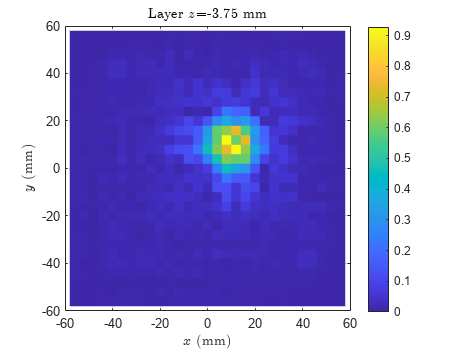

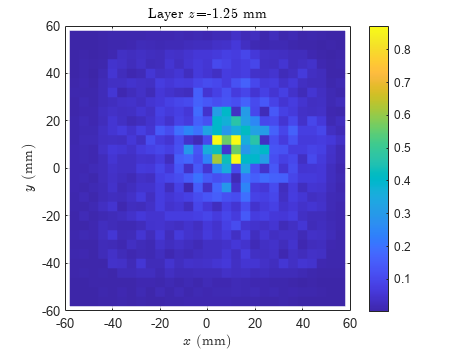

delta_B = B_m - B_bar;
delta_p = pagemtimes(R, delta_B);
clear B_m delta_B

layers = unique(elems_center(3,:));
for z = layers
    mask = elems_center(3,:) == z;
    x = elems_center(1,mask);
    y = elems_center(2,mask);
    n_x = length(unique(x));
    x = reshape(x, n_x, []);
    y = reshape(y, n_x, []);

    p = delta_p(mask,:,:);
    p = max(real(p), [], 3);
    p = reshape(p, n_x, []);

    figure
    surf(x*1e3, y*1e3, p, 'LineStyle','none');
    colorbar
    title(sprintf('Layer  $z$=%.2f mm', z*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
    box on
    axis square
    view(2)
end


clear layers mask n_x x y z p